# Module 4a: Fiducial marker drift correction

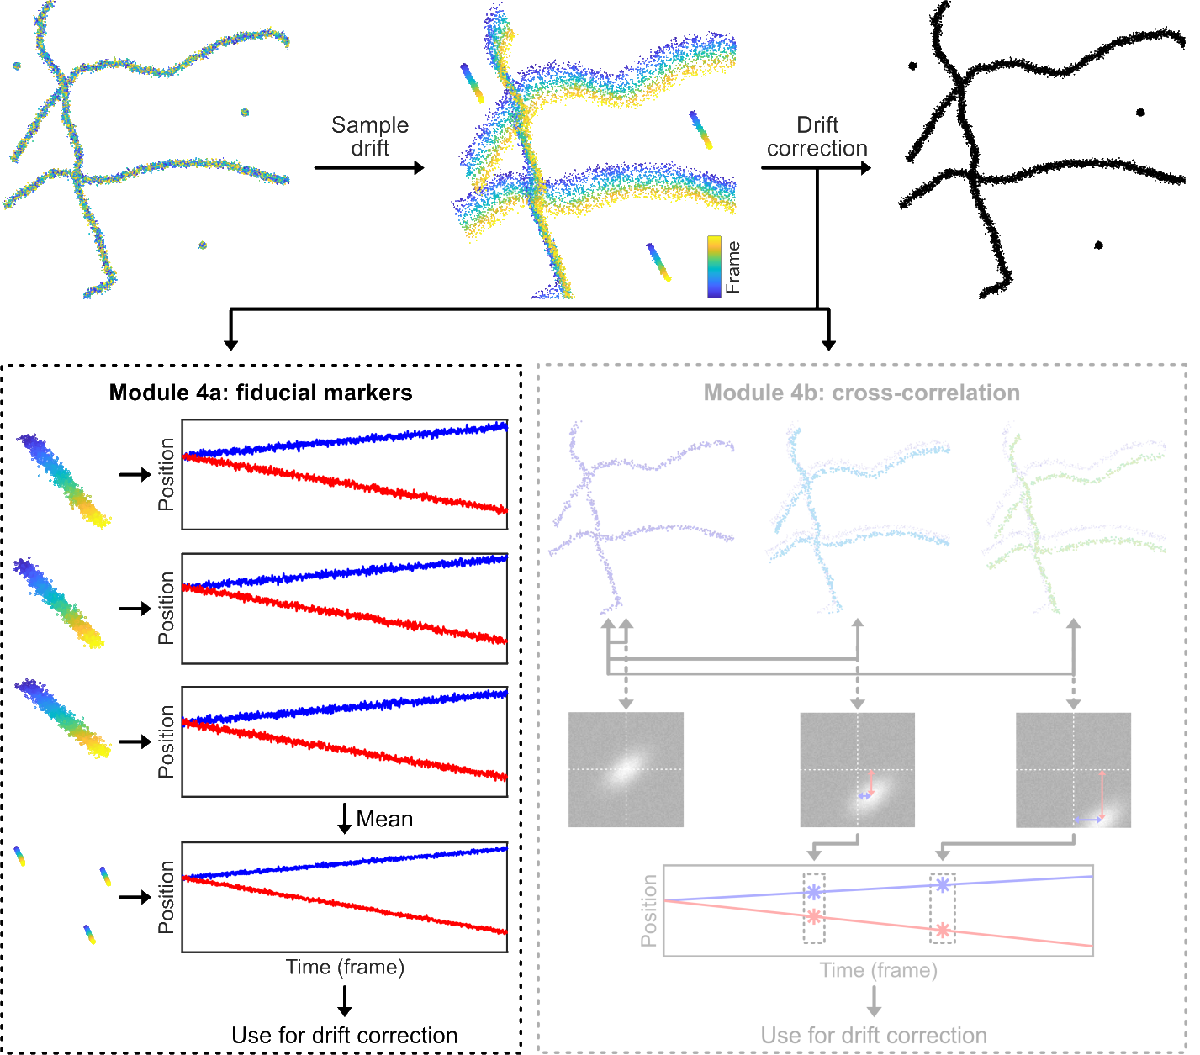

Drift correction based on fiducial markers requires identification of fiducial markers, calculting their average movement over the full movie duration, and subtracting that drift from the dataset. In this case, we simply assume that fiducial markers are localized at every frame in the movie, which means that we don't need to do any filtering based on fluorophore localization or intensity beforehand.

## Variable initialisation

clear all
% We specify the path to our file. In this example we explicitly name it "localization_file.txt" because the localization file to be processed is in the same folder as this notebook. In general we advise to provide a full path to the processed file, e.g.: 'mnt/project/localization_file.txt'
% file_path = 'Data/localization_file.txt';
file_path = 'Data/Ecoli_RNAP_fiducials_RAPIDSTORM.txt';

% We load a localization file via the readmatrix function
data = commonFunctions.readTXTRapidSTORM(file_path);

% The list of frames is put into uniqueFrame variable in parallel with the number of events per each frame.
% The result of this is simply an array of all frames that are encountered in the localization list, as well as an array with how many localizations are in all these frames. These arrays are used later.
[uniqueFrame, cumFrameLocCounts] = unique(data(:,1));

## Data tracking

The tracking of this data is identical to the tracking explained in module 3. Therefore, we will use the function created there. To understand how the trajectories are created, please look at module 3.

maxDistance = 100;

tracked_data = [data zeros(size(data,1),2)];
tracksCounter = 1;

for fr = 0:max(tracked_data(:,1))-1
    [tracked_data,tracksCounter] = commonFunctions.creating_trajectories(tracked_data,fr,fr+1,maxDistance,tracksCounter);
end

## Filtering trajectories to obtain fiducial marker data

Events from the fiducial markers should be present in all frames, therefore we can effectively filter out all-non-fiducial data by tracking only these events which have the nearest next-frame neighbor from the first upon the last frame.

% We need to define the first frame index based on the data
first_frame = tracked_data(tracked_data(:,1) == 1,:);

% The empty list in which all fiducial marker data will be stored is allocated.
fiducials = [];

% The code iterates through all events in the first frame. Most of these events are fiducial markers. 
% For each event a list of next-frame nearest neighbors will be created, which together will be a 
% fiducial marker trace.
fiducial_cell_id = 1;
for f = 1:size(first_frame,1)
    if first_frame(f,5) > 0
        fiducialCell{fiducial_cell_id} = tracked_data(tracked_data(:,5)==first_frame(f,5),:);
        fiducial_cell_id= fiducial_cell_id+1;
    end
end

% Finally, fiducials are filtered. If the fiducial trace is shorther then the movie, 
% it is being ignored and not processed further.
filtered_fiducials = {};
filtered_fiducial_cell_id = 1;
for f = 1:size(fiducialCell,2)
    if size(fiducialCell{f},1) == size(uniqueFrame,1)
        filtered_fiducials{filtered_fiducial_cell_id} = fiducialCell{f};
        filtered_fiducial_cell_id = filtered_fiducial_cell_id+1;
    end
end

## Drift correction based on found fiducial markers

Now that we have all the ficudals, we can start the process of removing the drift based on the movement of the fiducial markers. For this, first we must calculate the drift based on the fiducial markers...

% All fiducial drifts are recalculated relatively to their first datapoint, to get the actual drift over the movie
for i = 1:size(filtered_fiducials,2)
    % This only involves subtracting the x,y-position at the first frame from all other frames
    filtered_fiducials{i}(:,2:3) = filtered_fiducials{i}(:,2:3)-filtered_fiducials{i}(1,2:3);
end

% and an average drift trance is calculated. This drift trace will be used to perform a drift correction on each event in the dataset.
filtered_fiducials_sum = zeros(size(filtered_fiducials{1}));
for i = 1:size(filtered_fiducials,2)
    filtered_fiducials_sum = filtered_fiducials_sum+filtered_fiducials{i};
end
drift_trace = filtered_fiducials_sum(:,2:3)./size(filtered_fiducials,2);

We can visualise the traces of the individual fiducial markers, as well as the averaged one.

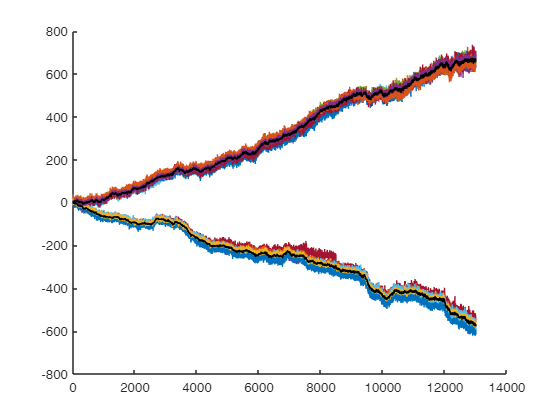

figure()
hold on
% We loop over all filtered fiducials
for k = 1:size(filtered_fiducials,2)
    % Plotting frame versus x position, randomly coloured
    plot(filtered_fiducials{k}(:,1),filtered_fiducials{k}(:,2)-filtered_fiducials{k}(1,2))
    % Plotting frame versus y position, randomly coloured
    plot(filtered_fiducials{k}(:,1),filtered_fiducials{k}(:,3)-filtered_fiducials{k}(1,3))
end
%And we also plot the average drift trace in black
plot([1:size(drift_trace,1)],drift_trace(:,1)-drift_trace(1,1),'k-')
plot([1:size(drift_trace,1)],drift_trace(:,2)-drift_trace(1,2),'k-')

And then we can remove the calculated drift from the complete dataset.

% In this for loop the drift correction is performed. The corrected position are stored in the last two columns, so the dataset contains XY-coordinates before and after correction.
% The code simply loops over every frame, finds the data belonging to that frame, and subtracts the found drift on that frame
for i = 1:size(uniqueFrame,1)
    fr = uniqueFrame(i);
    data(data(:,1) == fr, 5:6) = data(data(:,1) == fr, 2:3) - drift_trace(fr,:);
end

## Visualisation of drift correction by fiducial markers

Localizations can be visualized with scatter plots in order to see how the drift correction performed. In the upper scatter plot we can see the data before the drift correction and below after the drift correction.

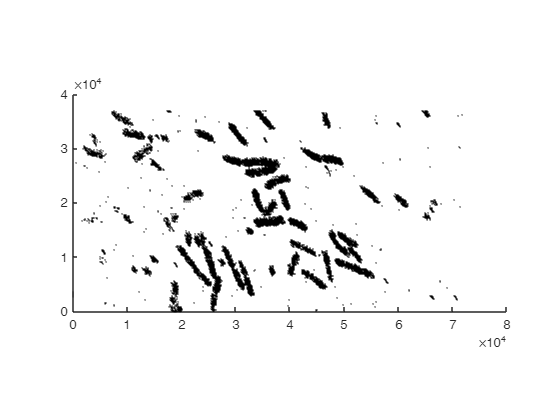

figure()
scatter(data(:,2), data(:,3), 0.5, 'k.');
axis equal
axis([0 8e4 0 4e4])

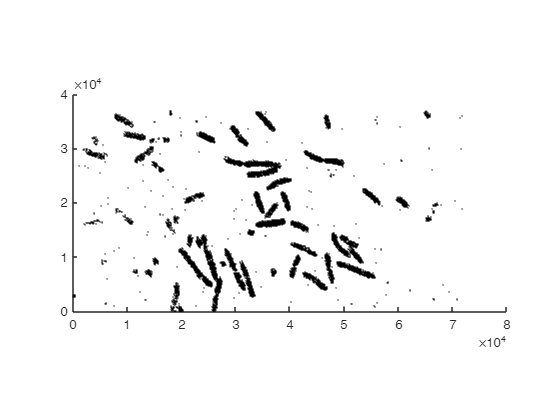


figure()
scatter(data(:,5), data(:,6), 0.5, 'k.');
axis equal
axis([0 8e4 0 4e4])